HW 2 David Cruz

1.11

To define appromixate pi we will generate random positive numbers inbetween 0 and 1 then take all the pairs whos distance is less than 1 which implies they lie in the unit circle. That function was written seperately. So,

We define our variables first, then compute error as n number of iterations increases. 

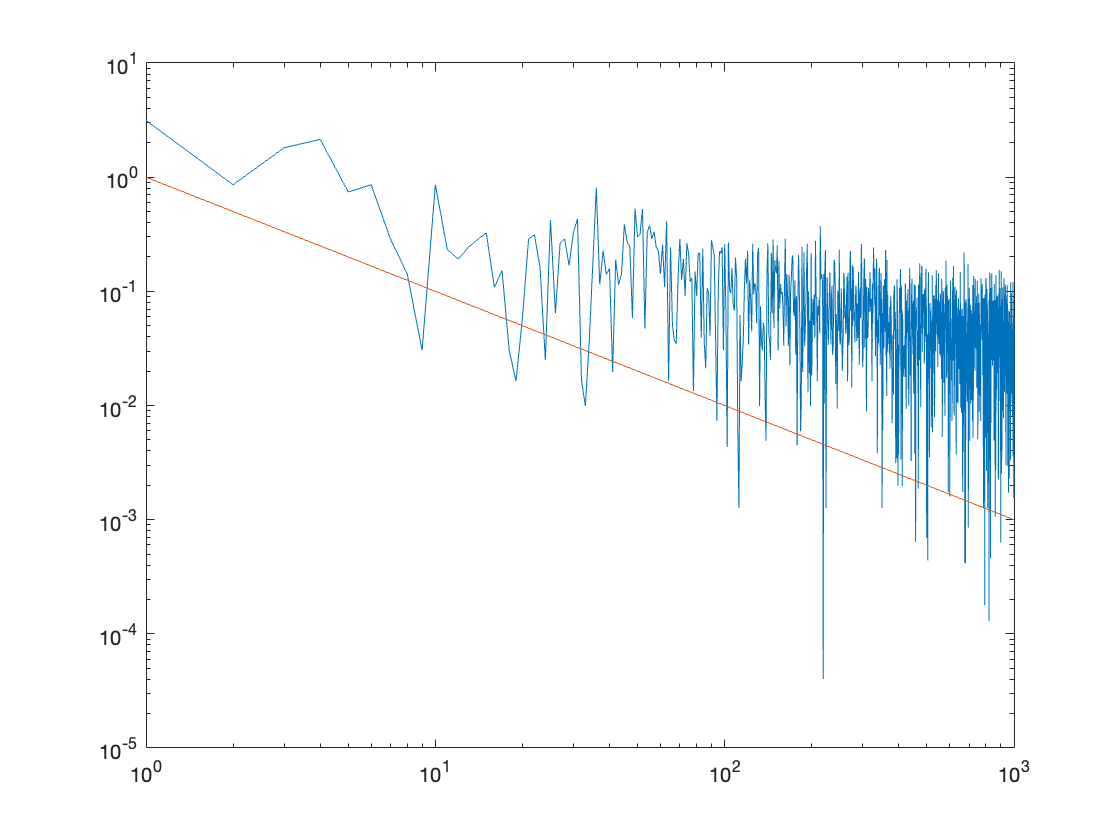

x = 1:1000;
y1 = 1:1000;
y2 = 1:1000;
for n= 1:1000
 y1(1,n)= abs(pi-pimc(n));% abs computational error
 y2(1,n)= 1/n; % this makes the h = 1/n we will use later to check linear 
end
loglog(x,y1,x,y2)

From the graph we can estimate the slope is close to parellel with 1/n line.  Slightly less steep than the 1/n making the slope less than -1.

As n increases our error decreases linearly.

1.14

We will write the fibonacci sequence in 2 different funcitons. One will be recurvise add the previous 2 numbers n times. The second will use matrix muplication to create our fibonacci sequence in a matrix.

t = cputime

t = 66.9700

fn = fibrec(10) 

fn = 55

cpu= cputime - t

cpu = 0.0500

t1 = cputime

t1 = 67.0300

fn1 = fibmat(10)

fn1 = 55

cpu1= cputime - t1

cpu1 = 0.0200

The matrix method works faster than the recursive method. Matlab is geared towards matrix manipuliation so this follows that purpose.  

Functions are below

function api = pimc(n)
x = rand(n,1); 
y = rand(n,1); 
z = x.^2+y.^2;
r = (z <= 1);
m=sum(r);
api=4*m/n;
end
function f=fibrec(n) 
if n == 0
    f = 0; 
elseif n == 1
    f = 1; 
else
    f = fibrec(n-1)+fibrec(n-2);
end
end

function f1=fibmat(n)    
f1 = [0;1];
A = [1 1; 1 0];
f1 = A^n*f1;
f1 = f1(1);
end